clc;
close all;
clear all;

x = input('Enter the sequence: ');  % Input sequence
n = input('Enter the value of N: ');  % Number of points for N-point DFT
ndft = fft(x, n);  % Compute N-point DFT of the input sequence

% Display the DFT values (complex values)
disp('DFT values:');

DFT values:


disp(ndft);

   2.0000 + 0.0000i   1.0000 - 1.0000i   0.0000 + 0.0000i   1.0000 + 1.0000i




v=abs(ndft);
disp('After calculating the magnitude the values: ');

After calculating the magnitude the values: 


disp(v);

    2.0000    1.4142         0    1.4142



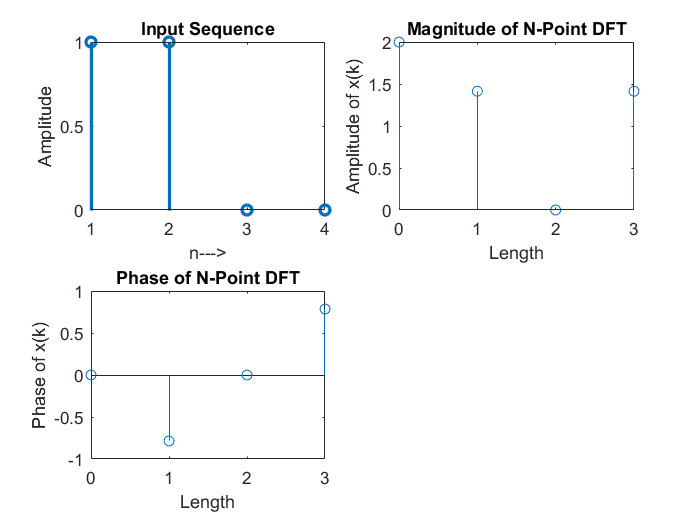


subplot(2,2,1);
stem(x,'linewidth',2);
xlabel("n--->");
ylabel("Amplitude");
title("Input Sequence");

% Magnitude of the DFT
m = abs(ndft);
N = 0:1:n-1;
subplot(2,2,2);
stem(N, m,'linewidth',2);
xlabel('Length');
ylabel('Amplitude of x(k)');
title('Magnitude of N-Point DFT');

% Phase of the DFT
p = angle(ndft);
subplot(2,2,3);
stem(N, p,'linewidth',2);
xlabel('Length');
ylabel('Phase of x(k)');
title('Phase of N-Point DFT');